# Segmentations

### Loading

clear;clc;
fname1 = "data1\";
fname2 = "data2\";

s1 = dir(fname1);
s2 = dir(fname2);

I1 = zeros(length(1)-2, 512, 512);
I2 = zeros(length(2)-2, 512, 512);

for i = 3:length(s1)
    I1(i-2, :, :) = dicomread(fname1 + dname(i-3));
end

for i = 3:length(s2)
    I2(i-2, :, :) = dicomread(fname2 + dname(i-3));
end

# Region growing

I = squeeze(I1(10, :, :));
[Id, Is, Ib] = RGSegm(I);

figure('Position', [0 0 1500 600]);
subplot(1, 3, 1);
imshow(Id, []);
title('Original')
subplot(1, 3, 2);
imshow(Is, []);
title('Regions');
subplot(1, 3, 3);
imshow(Ib, []);
title('Binary');

### Matlab Built-in segmentator

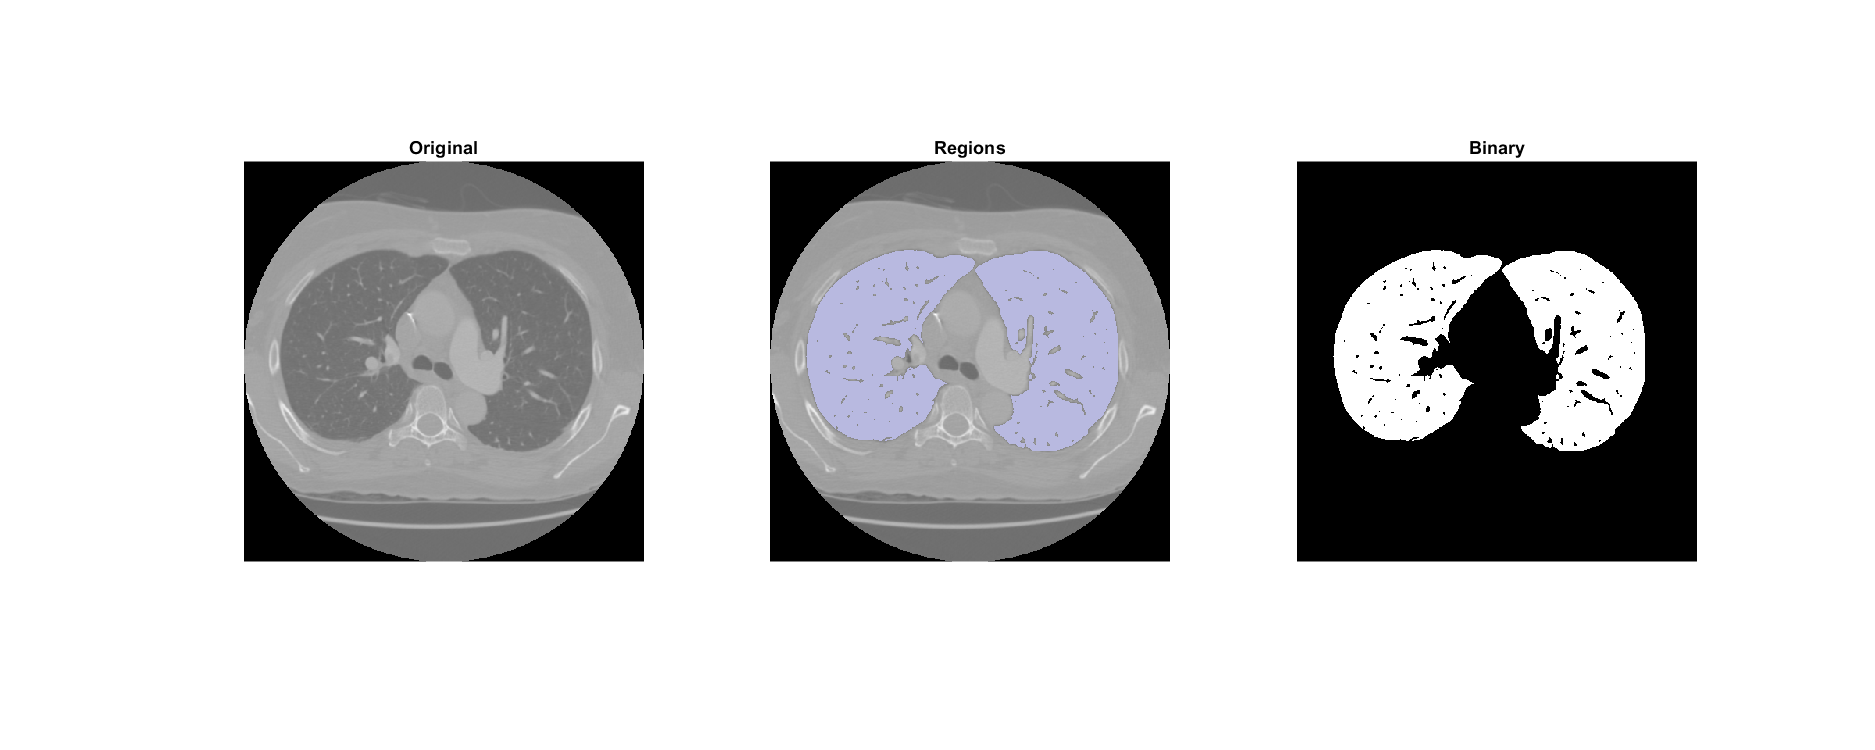

% clear;clc;
I = squeeze(I1(10, 10:510, 10:510)); % input


I = I - min(min(I));
I = I / max(max(I));
% I = I;
J = zeros(size(I, 1), size(I, 2), 3);
% I = rgb2gray(I);
regions = detectMSERFeatures(I, 'RegionAreaRange', [2000, 200000]);
colors = randi(255, regions.Count, 3);
for i = 1:regions.Count
    Px = regions.PixelList{i, 1};
    for j = 1:size(Px, 1)
        J(Px(j, 2), Px(j, 1), :) = colors(i, :);
    end
end

figure();
plot(regions,'showPixelList',true,'showEllipses',false);

#### Thresholding

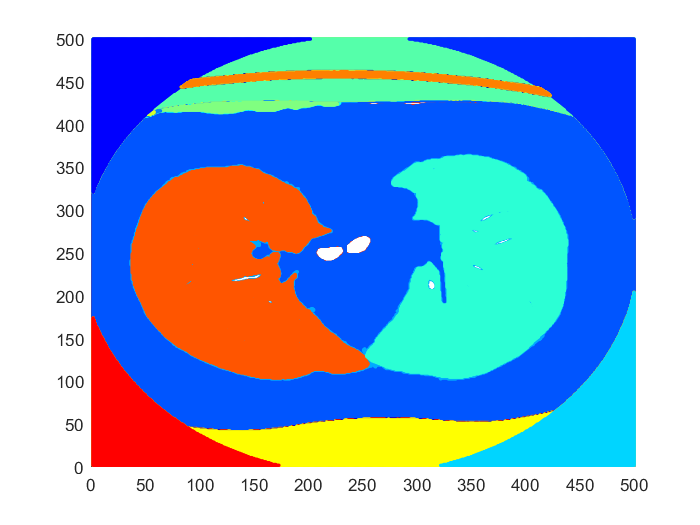

figure('Position', [0 0 1500 600]);
subplot(1, 2, 1);

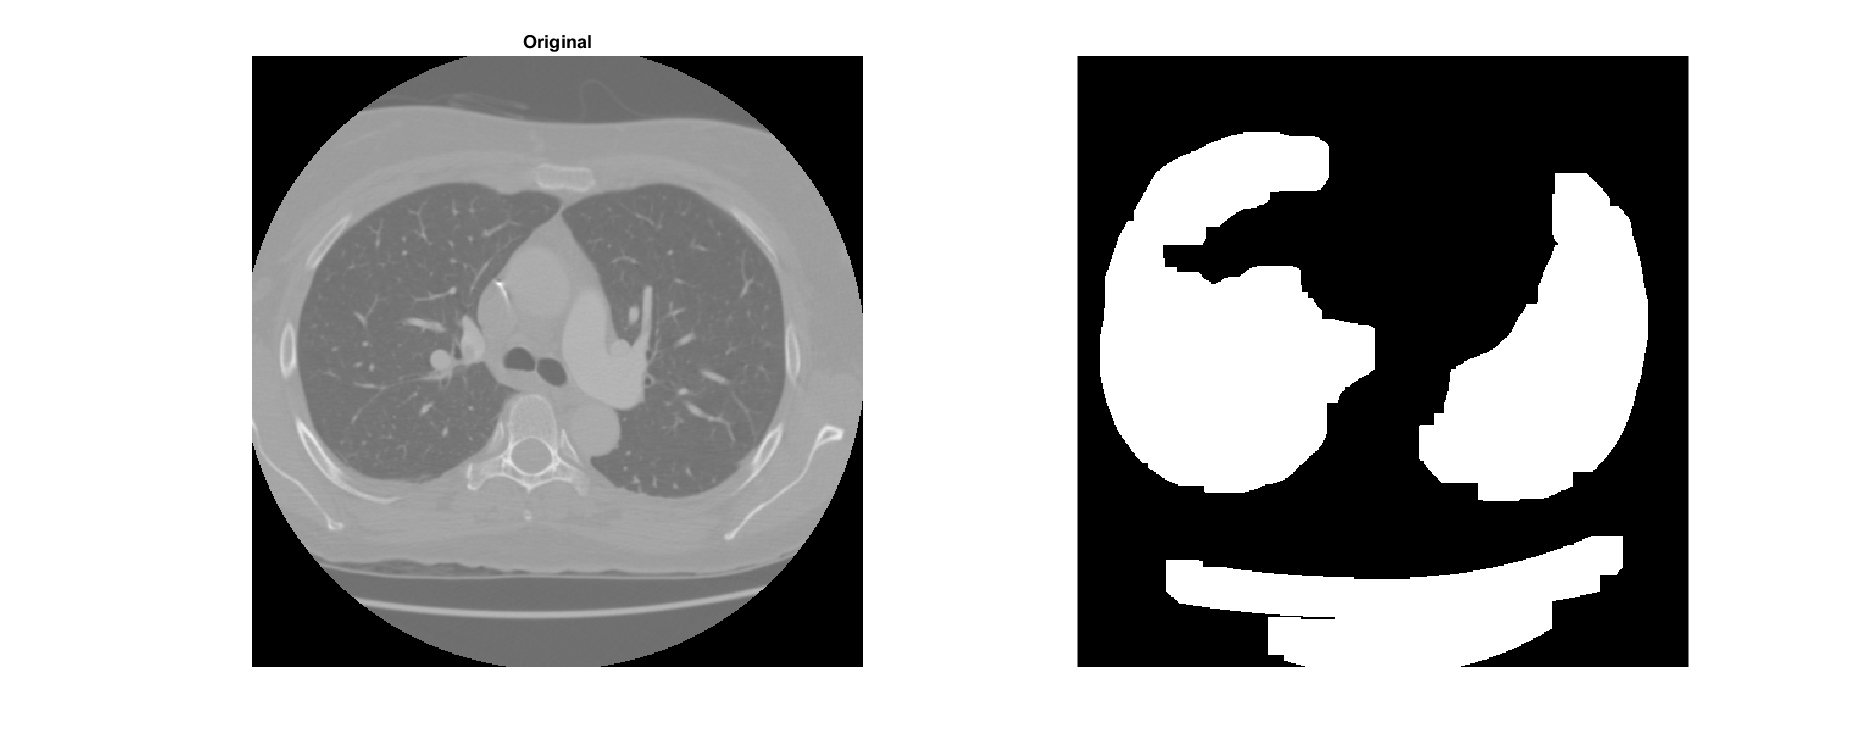

imshow(I, []);title('Original');

I = squeeze(I1(5, :, :));
I = I - min(min(I));
I = I / max(max(I));
I = I*255;

J1 =  I < 160;
J2 = I > 120;
J = J1 .* J2;

J = bwmorph(J, 'erode', 7);
J = bwmorph(J, 'dilate', 5);
J = bwmorph(J, 'dilate', 5);
J = bwmorph(J, 'dilate', 3);

subplot(1, 2, 2);
imshow(J, []);

# End